# Sampling data

You've just finished the complete machine learning workflow with the Taxi data. You're now ready to apply this workflow to your own data. The first steps will be the exploratory data analysis, data processing, and feature engineering steps you learned about in the previous courses.

One decision you may have to make is whether to sample the data before training. Very large datasets, or "big data", are common in today's data-filled world. Sampling is a tool that can help you deal with large datasets.

In the beginning of this course, you were told that the Taxi data from this course represented 2% of the full dataset available on [https://www1.nyc.gov/site/tlc/about/tlc-trip-record-data.page](https://www1.nyc.gov/site/tlc/about/tlc-trip-record-data.page). This 2% was selected randomly, or "sampled", from the full dataset.

In this reading, you will learn how to sample random observations from a table of data and how to choose the number of samples to ensure good model performance. You'll see these steps performed with the taxi data, and at the end, you'll see a model trained and evaluated on a full month of taxi data (~10,000,000 observations).

**A quick warning: **Running the code below on your own is **not recommended! **The code downloads a large file (~2 GB) from the internet and loads it into MATLAB. It then uses this data to train an ensemble of decision trees. The whole process requires a significant amount of time and memory. Therefore, you only need to read through the code and observe the outputs.

answer = questdlg("You do not have to run this script. It downloads a large file from the internet (~2 GB) " + ...
    "and uses it to train a model. This takes a significant amount of time and memory. Do you wish to continue?", ...
    "Run this script?","Yes","No","No");
if strcmp(answer,'No')
    return;
end

## Download full month of data

Download one month of data from the NYC Taxi and Limousine Commission (TLC) website. This file is ~2 GB, so it will take a long time to download with a slow internet connection.

filename = "yellow_tripdata_2015-05.csv";
source = "https://s3.amazonaws.com/nyc-tlc/trip+data/" + filename;
websave(filename,source)

ans = 'E:\Datasets\Taxi data\yellow_tripdata_2015-05.csv'

Read in the full month of data. Given the large file size, the load process can also take a long time.

taxiFull = importTaxiDataWithoutCleaning(filename);
height(taxiFull)

ans = 13158262

head(taxiFull)

ans = 8×19 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge
    ______    ___________________    ___________________    __________    ________    _________    _________    ________    ________    __________    __________    ___________    ____  

## Split off a test set

Once you import the data, you can begin exploratory data analysis. This may include sampling the data to make it easier to work with. However, after your intial exploration it's important to return to the raw, *unsampled* dataset and split off a test set before training any models.

One of the dangers with random sampling is the potential to have duplicate datapoints in both the training and test data sets. This can happen if you sample **with replacement** before splitting off the test set. The term "sampling with replacement" means that after a datapoint has been sampled, it is placed back into the pool of potential datapoints and potentially sampled again.

To avoid this, it's usually better to sample **without replacement,** so datapoints cannot be sampled more than once. You'll learn about an exception to this rule later in the lesson when it comes to dealing with class imbalances.

The datasets you've been using in this course were sampled without replacement, so there weren't any duplicate datapoints when you first created a test set. Nevertheless, those test sets were technically created *after *sampling 2% of the raw data. This was an intentional decision used to help teach the concepts in this course without having to deal with gigabytes of data. In practice, it is safer to split off a test set *before* sampling in order to ensure the test set has not been contaminated.

To demonstrate, the code below creates a test set using 20% of the raw data before any sampling.

rng(1);
cv = cvpartition(height(taxiFull),"HoldOut",0.2);
taxiTest = taxiFull(test(cv),:);
taxiTrain = taxiFull(training(cv),:);

At this point, the full dataset is duplicated by the separate variables `taxiTrain` and `taxiTest`, so it can be cleared from memory.

clear taxiFull

## How to sample randomly from data

The function `datasample` allows you to sample rows from a table with and without replacement. 

The code below creates a small dataset with 1,000 points from the training dataset. The "Replace" option is set to false to specify sampling without replacement.

numSample = 1000;
taxiSample = datasample(taxiTrain,numSample,"Replace",false);
height(taxiSample)

ans = 1000

head(taxiSample)

ans = 8×23 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax    Tip     Tolls    ImpSurcharge    TotalCharge    Duration    AveSpeed    TimeOfDay    DayOfWeek
    ______    ___________________    ___________________    __________    ________    _________    _________    ________    ________   

## Preprocess data

At this point, you can perform steps like preprocessing and feature engineering to prepare the data for machine learning. For the taxi data, this includes the basic pre-processing that removes outliers and adds important features like time of day.

taxiSample = basicPreprocessing(taxiSample);
taxiSample = addTimeOfDay(taxiSample);
taxiSample = addDayOfWeek(taxiSample);

Use the same preprocessing steps on the full set of training data. This is needed to help select a sample size as well as train the final model.

taxiTrain = basicPreprocessing(taxiTrain);
taxiTrain = addTimeOfDay(taxiTrain);
taxiTrain = addDayOfWeek(taxiTrain);

## Is the sample large enough?

One way to quickly check whether your sampled data accurately reflects the distribution of values in the full data is to create histograms. Most of the regression models in the course were trying to predict the taxi trip duration, so the plot below shows the duration histograms from both the sampled data and the full data. 

The full data is plotted as a blue stairstep line graph, while the sampled data is plotted as a filled orange shape. If you see the orange histogram tracing the shape of the blue histogram, then the two histograms are similar. In other words, the distribution of the sampled data is a good representation of the full data.

Note that the histograms use a "Normalization" option to account for the different number of observations.

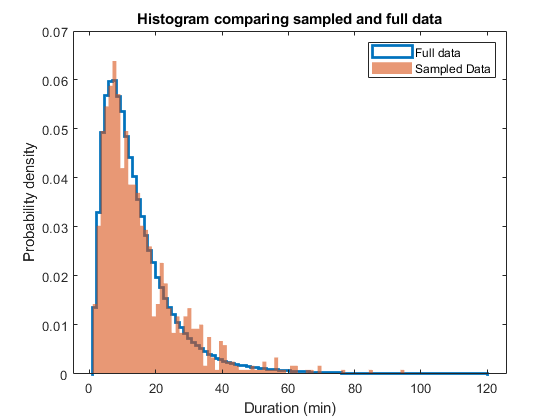

plotDurationHistograms(taxiTrain,taxiSample)

It seems like the sampled data does a fair job of representing the common trips with durations less than 30 minutes. But how about the less common trips? The plot below is the same histogram but zoomed in on the tail of the distribution. Does this sample of 1,000 datapoints do a good job of representing the trips with long durations?

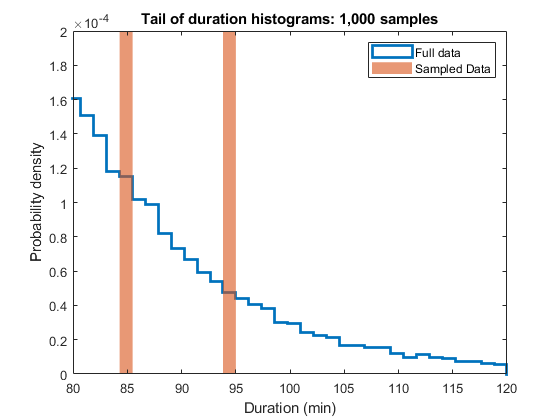

plotDurationHistograms(taxiTrain,taxiSample)
xlim([80 120])
ylim([0 2e-4])
title("Tail of duration histograms: 1,000 samples")

## How big should the sample be?

The sample with 1,000 datapoints is clearly too small for representing the full distribution of duration values but choosing the *right* number of samples is a difficult problem. There are several ways for evaluating whether a sample comes from a particular distribution, such as hypothesis testing. However, comparing the histograms for different size samples is one quick way to evaluate the sample size.

The figures below compare the histograms with 100,000 and 1,000,000 samples. They both zoom in on the tail of the distribution. How do the different sample sizes compare at representing the less common trips with long durations?

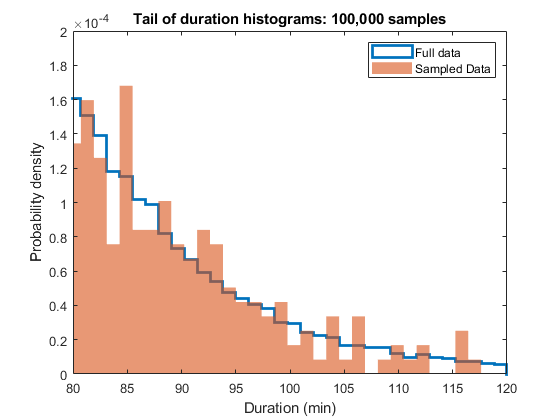

% Plot histograms with 100,000 samples. Zoom in on tail
taxiSample = datasample(taxiTrain,1e5,'Replace',false);
plotDurationHistograms(taxiTrain,taxiSample)
xlim([80 120])
ylim([0 2e-4])
title("Tail of duration histograms: 100,000 samples")

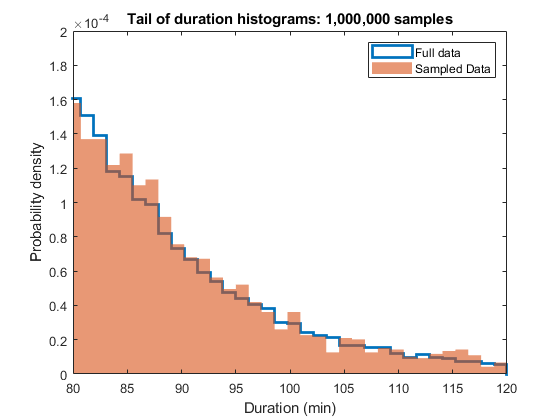

% Plot histograms with 1,000,000 samples. Zoom in on tail
taxiSample = datasample(taxiTrain,1e6,'Replace',false);
plotDurationHistograms(taxiTrain,taxiSample)
xlim([80 120])
ylim([0 2e-4])
title("Tail of duration histograms: 1,000,000 samples")

The sample with 100,000 does a much better job at representing the less common trips than 1,000 samples. The sample with 1,000,000 datapoints does even better still, but it's likely too big for rapid exploration and model testing. 

The taxi datasets you've been using so far in this course contained 2% of the full data. For the month of May, that translates to ~200,000 datapoints. This size was chosen because it did a fair job at representing the full dataset, while still allowing for decently fast model training and exploration.

## Choosing a sample size by training models

Another way to help choose a sample size is to train a simple model with different sample sizes and compare the performance. If you train enough models, you can construct a "learning curve" that shows the validation error (e.g. RMSE) as a function of the sample size. Below is an example of a learning curve.

A good choice for the number of samples would be where the model performance begins to plateau. That way you can have a small sample while still being confident that a larger sample will not produce significantly better performance.

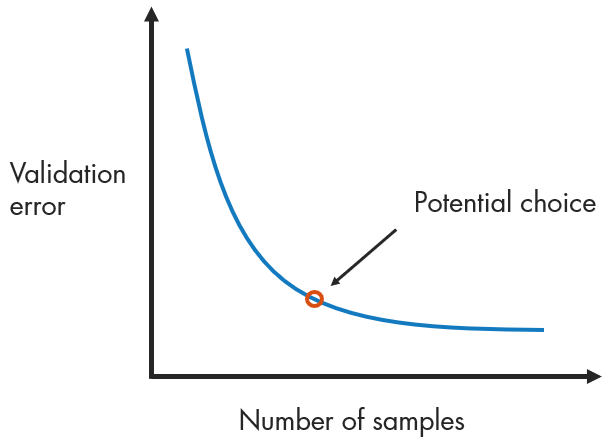

**Warning: **constructing a learning curve can take a long time, and the shape of the curve will depend heavily on the model complexity. A simple model like linear regression model will plateau much more quickly than a more complex model like a bagged ensemble. If you choose the number of samples based on a simple model, you could be biased during the model selection phase. You might miss potential performance gains that could be achieved using a complex model with a larger sample.

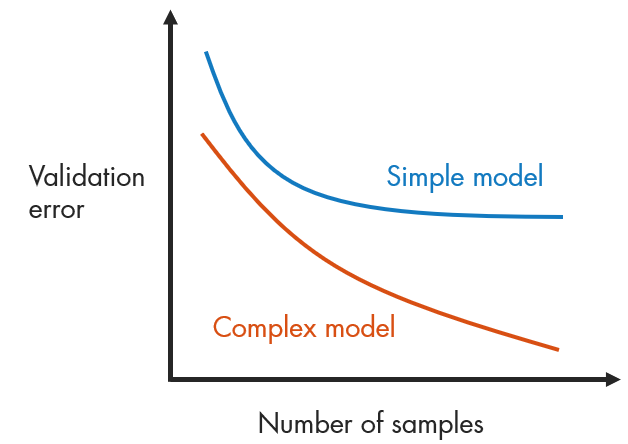

Choosing a sample size with a learning curve is difficult. But it can be useful if the amount of time spent choosing a sample size is less than the extra time it would take to decide on a final model with a very large sample (i.e. the time to choose a model type and tune hyperparameters).

## Recreate the sampled data from this course

Once you've chosen the sample size, you can use `datasample` to create the sampled dataset. Below is the code used to create the datasets you've used so far in this course. The `ceil` function is used to round the number of samples to an integer value.

percentToSample = 2;
numSample = ceil(height(taxiTrain)*percentToSample/100);
taxiSample = datasample(taxiTrain,numSample,'Replace',false);
height(taxiSample)

ans = 204607

head(taxiSample)

ans = 8×23 table
    Vendor        PickupTime             DropoffTime        Passengers    Distance    PickupLon    PickupLat    RateCode    HeldFlag    DropoffLon    DropoffLat      PayType      Fare    ExtraCharge    Tax     Tip     Tolls    ImpSurcharge    TotalCharge    Duration    AveSpeed    TimeOfDay    DayOfWeek
    ______    ___________________    ___________________    __________    ________    _________    _________    ________    ________  

This is the dataset used for choosing a model type, selecting features, and tuning hyperparameters. All of these decisions make up your selection of a final model. 

## Final model training

After you've made the selection of a final model, you should train it on the full dataset if possible. The code below trains a bagged tree ensemble with the entire set of training data. The hyperparameter values are the ones you found earlier when optimizing a bagged ensemble. Note the `"NPrint"` option set below will print out a message after each set of 5 trees are trained. 

mdl = fitrensemble(taxiTrain,"Duration", ...
    "PredictorNames",["Distance","TimeOfDay","DayOfWeek", ...
    "PickupLat","PickupLon","DropoffLat","DropoffLon"], ...
    "Method","Bag", ...    
    "Learners",templateTree("MinLeafSize",6), ...            
    "NumLearningCycles",40, ...
    "NPrint",5);

Training Bag...
Grown weak learners: 5
Grown weak learners: 10
Grown weak learners: 15
Grown weak learners: 20
Grown weak learners: 25
Grown weak learners: 30
Grown weak learners: 35
Grown weak learners: 40


## Evaluate the final model 

Once the final model is trained, you evaluate the final model with the test set. First, you must apply the same pre-processing steps.

taxiTest = basicPreprocessing(taxiTest);
taxiTest = addTimeOfDay(taxiTest);
taxiTest = addDayOfWeek(taxiTest);

Then use the `predict` function to get the predicted durations and the `rMetrics` function to see the metric values.

yPredict = predict(mdl,taxiTest);
rMetrics(taxiTest.Duration,yPredict)

ans = 1×4 table
     mae      mse       rmse       Rsq  
    _____    ______    ______    _______

    2.702    18.598    4.3126    0.85711


The performance is quite good. The RMSE found earlier when training on the sampled data was ~4.7, so the model trained on the full dataset decreased the error by ~0.4 minutes. The $R^2$ value increased from ~0.81 to ~0.86. Also, the MAE value implies that the predicted durations differ from the actual values by ~2 minutes, 40 seconds on average. 

#### Appendix: Helper function

This function plots the duration histograms to compare sample sizes

function plotDurationHistograms(taxiFull,taxiSample)

    % Plot full data with "stairs" option 
    h1 = histogram(taxiFull.Duration,100, ...
        "Normalization","pdf","DisplayStyle","stairs","LineWidth",2);
    
    % Plot sampled data with "bar" option using the same histogram bins
    hold on
    histogram(taxiSample.Duration,h1.BinEdges, ...
        "Normalization","pdf","DisplayStyle","bar",'EdgeColor',"none");
    hold off
    
    % Add legend and labels
    legend(["Full data","Sampled Data"])
    title("Histogram comparing sampled and full data")
    xlabel("Duration (min)")
    ylabel("Probability density")

end